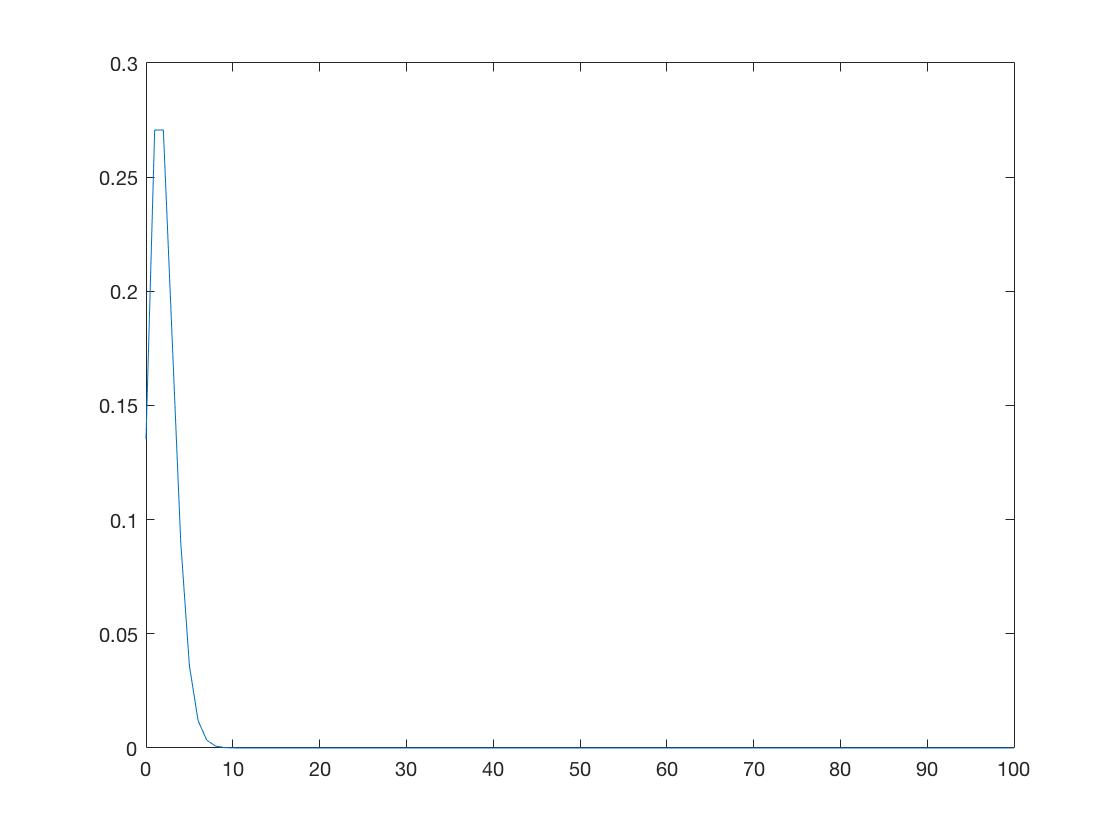

% PHYS 434
% LAB 2
% Jin Kyoung Lee


% Problem 1
% Background of cosmic-rays follow a Poisson distribution
% In 1 day the average cosmic-ray background: X = lambda(λ) = 2
% The average number of gamma-rays emitted by the hypothetical
% source: Y = 4

% A) Cosmic-rays
% Day 1
background = 2;
x0 = linspace(0, 100, 101);
p1Day = poisspdf(x0, background); % Create Poisson distribution with lambda = 2
plot(x0, p1Day);

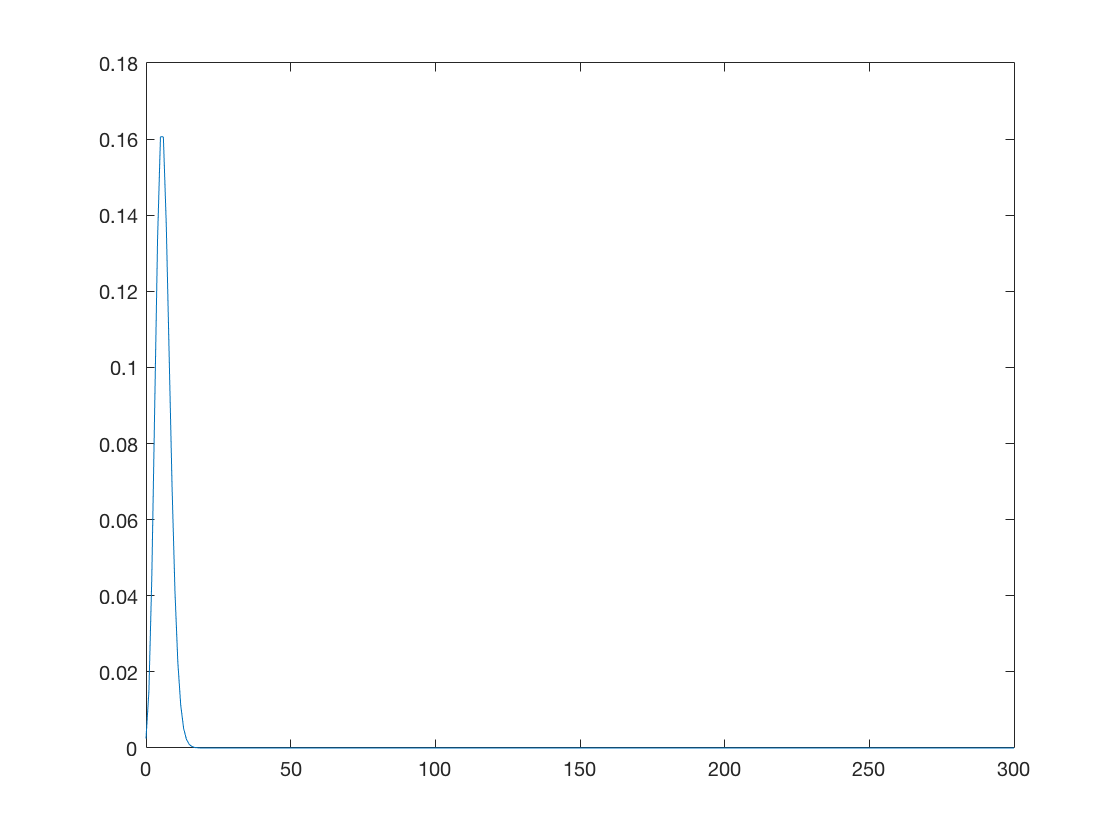

% Using convolution to get the probability distribution for more days
numOfDays = 3; % 3 days
p3Days = p1Day;
for i = 1:numOfDays-1
    p3Days = conv(p3Days, p1Day);
end
x = linspace(0, 100*numOfDays, 100*numOfDays+1);
plot(x, p3Days)

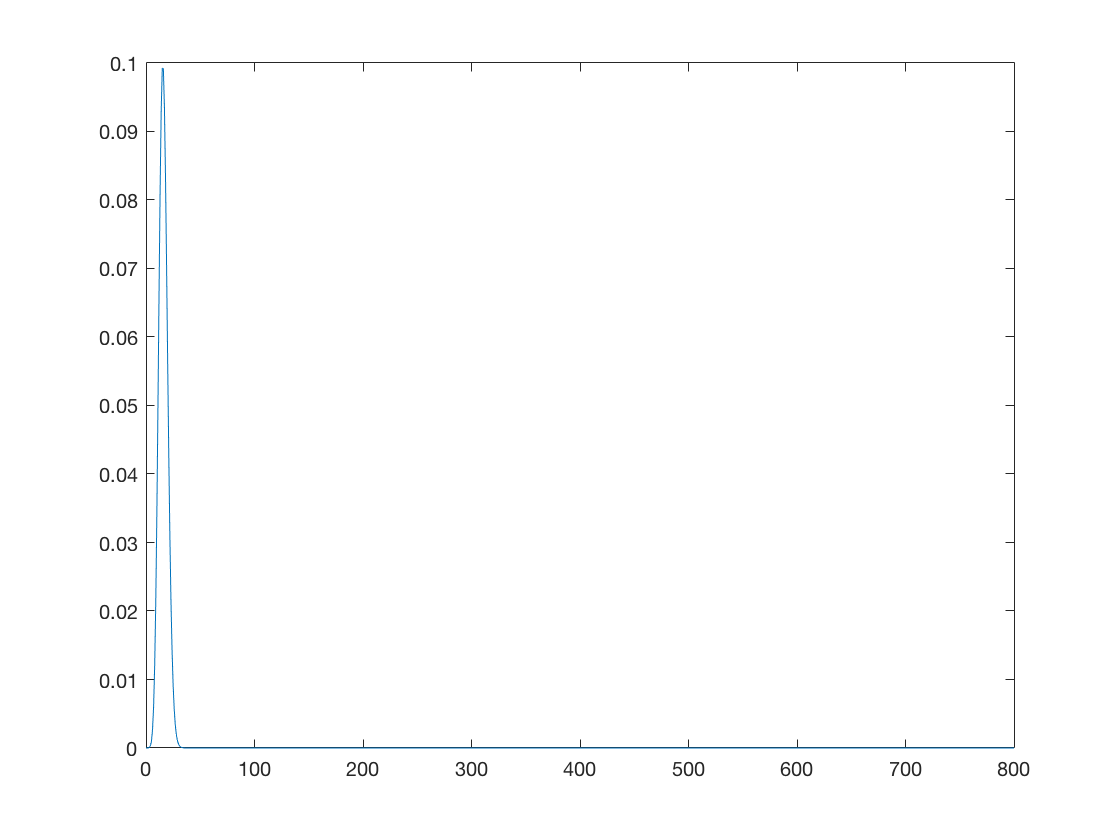

% From the result above, we can see that both the graph for a day and the
% graph for 3 days follow Poisson distribution.

% B)
% Also using convolution to get the probability distributino after 5 days
numOfDays = 8; % Choosing the value greater than 5
p8Days = p1Day;
for i = 1:numOfDays-1
    p8Days = conv(p8Days, p1Day);
end
x = linspace(0, 100*numOfDays, 100*numOfDays+1);
plot(x, p8Days)

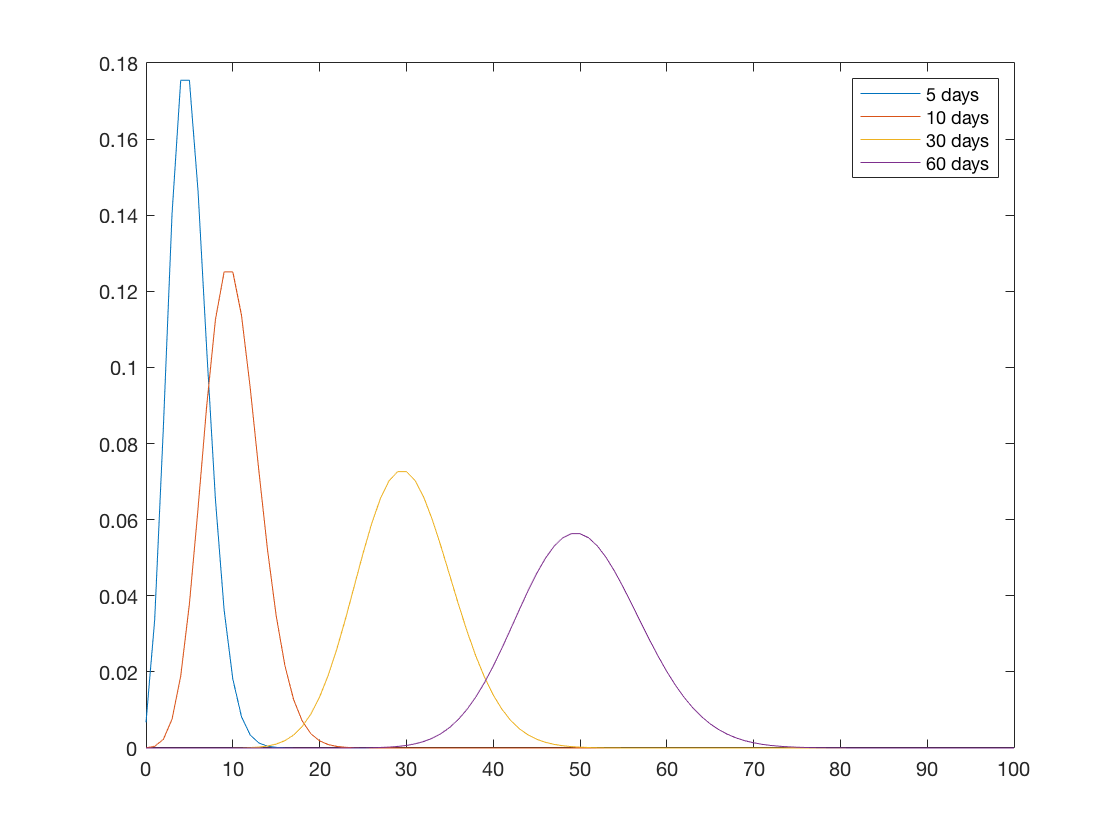

% From part A), we found that adding probability distribution for 3 days
% was still a Poisson distribution. Also, here in part B), by using
% the same method that of part A), it is proved that after 5 days,the
% summed probability disdtribution is still A Poisson distribution.
% ******mathematical and conceptual explanation need to be added.******
% Convolution means adding two distribution, therefore, the summed
% distribution will remain as a Poisson ditribution.

% C)
x1 = linspace(0,100,101);
% Averaging 5 days
p5Days = poisspdf(x1, 5);

% Averaging 10 days
p10Days = poisspdf(x1, 10);

% Averaging 30 days
p30Days = poisspdf(x1, 30);

% Averaging 50 days
p50Days = poisspdf(x1,50);

% Plotting distributions to compare the shape
plot(x1,p5Days)
hold on
plot(x1,p10Days)
plot(x1,p30Days)
plot(x1,p50Days)

legend('5 days','10 days','30 days','60 days')
hold off

% As the average days increases, the distribution becomes normal
% distribution
% ********* EXPLANATION NEEDS TO BE ADDED!!!!!!!!!!!!!

% D) Number of days: N = 3
% Gamma rays from the source: Y*N = 4 * 3 = 12
poissCosRays = makedist("Poisson",'lambda',background);
pGammaRays = 1 - cdf(poissCosRays, 12)

pGammaRays = 2.0735e-07

sigma = icdf('Normal',1-pGammaRays,0,1)

sigma = 5.0621

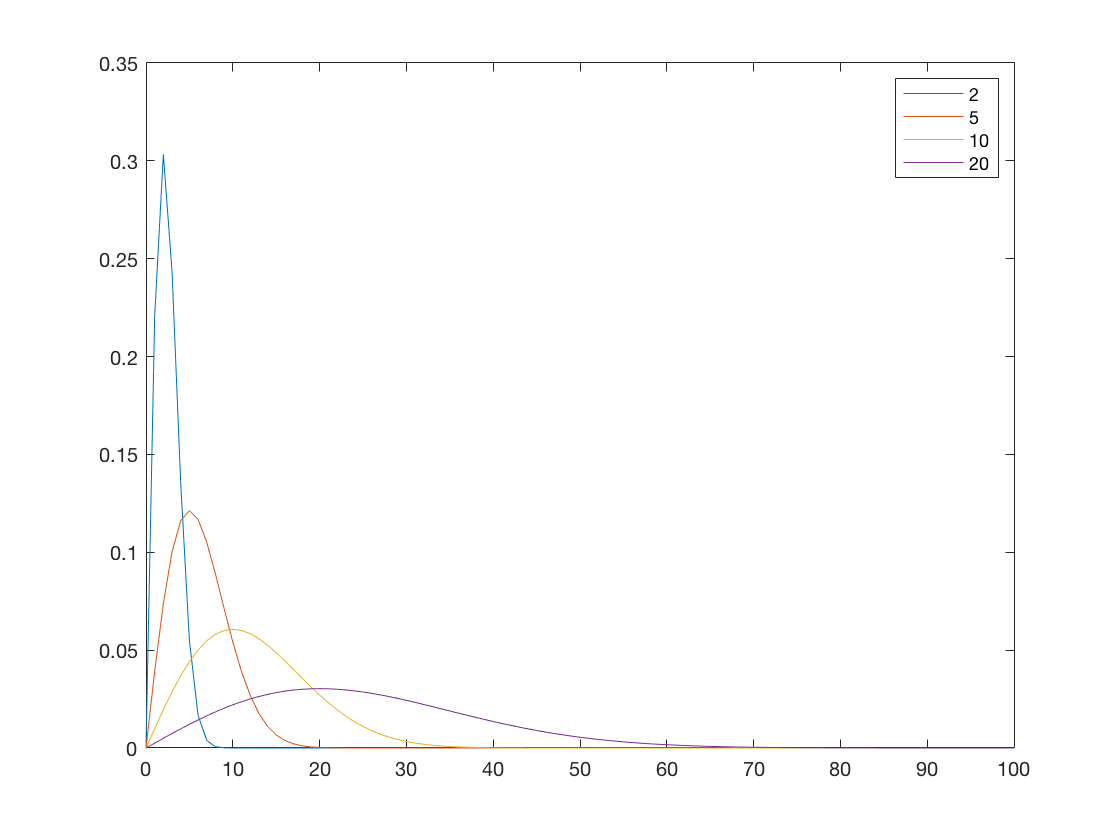

% Problem 2

x2 = linspace(0,100,101);
% parameter = 2
r2 = raylpdf(x2,2);
% parameter = 5
r5 = raylpdf(x2,5);
% parameter = 10
r10 = raylpdf(x2,10);
% parameter = 20
r20 = raylpdf(x2,20);

% Plotting
plot(x2,r2)
hold on
plot(x2,r5)
plot(x2,r10)
plot(x2,r20)

legend('2','5','10','20')
hold off

% Yes, it approaches a Gaussian distribution as the parameter gets larger.
% This happenes when the parameter exceeds 5.


% Problem 3

% Version 1
% Width of the bacckground Gaussian distribution: X = 5
% Signal of strength: Y = 0.05